%% Machine Learning
% Lab 1: Linear Regression with One variable
% --- Profit in City ----
%{
In this part of this exercise, you will implement linear regression with one
variable to predict pro�ts for a food truck. Suppose you are the CEO of a
restaurant franchise and are considering di�erent cities for opening a new
outlet. The chain already has trucks in various cities and you have data for
pro�ts and populations from the cities.
You would like to use this data to help you select which city to expand
to next.
%}


%% Initialization
clear ; close all; clc

%Read Data...
data=load('ex1data1.txt');
data

data =     6.1101   17.5920
    5.5277    9.1302
    8.5186   13.6620
    7.0032   11.8540
    5.8598    6.8233
    8.3829   11.8860
    7.4764    4.3483
    8.5781   12.0000
    6.4862    6.5987
    5.0546    3.8166


% Parsing the data
X = data(:, 1);
Y = data(:, 2);
m = length(Y); % number of training examples

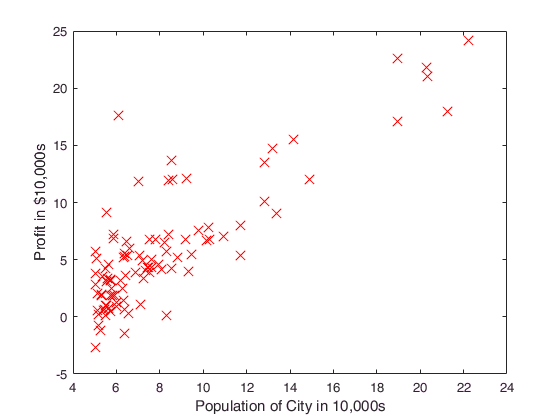

figure;                                   % open a new figure window
plot(X, Y, 'rx', 'MarkerSize', 10);       % Plot the data
ylabel('Profit in $10,000s');             % Set the y-axis label
xlabel('Population of City in 10,000s');  % Set the x-axis 

X = [ones(m, 1), data(:,1)]; % Add BIAS: additional column of ones to X
w = zeros(2,1);              % Initialize fitting parameter (weights)

% Some gradient descent setting
epochs = 1500;
learning_rate = 0.01;

%Testing the Cost Function / Error Function ...

% compute and display initial cost
C = computeCost(X,Y,w);
fprintf('With theta = [0 ; 0]\nCost computed = %f\nExpected cost value (approx) 32.07\n', C);

With theta = [0 ; 0]
Cost computed = 32.072734
Expected cost value (approx) 32.07


% further testing of the cost function
C = computeCost(X, Y, [-1 ; 2]);  %modified weights
fprintf('With theta = [-1 ; 2]\nCost computed = %f\nExpected cost value (approx) 54.24\n', C);

With theta = [-1 ; 2]
Cost computed = 54.242455
Expected cost value (approx) 54.24


% Gradient Descent ...
w = gradientDescent(X, Y, w, learning_rate, epochs);
% print weights to screen
w % Expected:  -3.6303 1.1664

w =    -3.6303
    1.1664


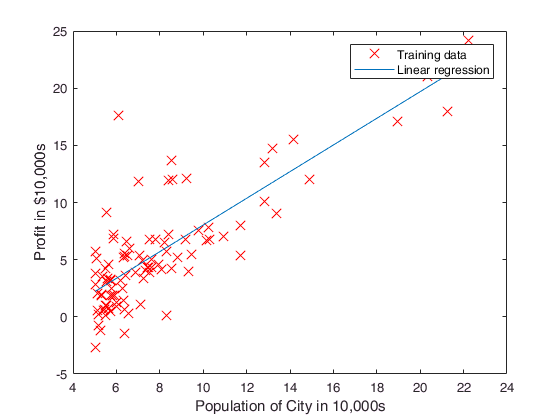

%% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*w, '-') % X*w is Y_estimated
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

%%  Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *w;
fprintf('For population = 35,000, we predict a profit of %f\n',...
    predict1*10000);

For population = 35,000, we predict a profit of 4519.767868


predict2 = [1, 7] * w;
fprintf('For population = 70,000, we predict a profit of %f\n',...
    predict2*10000);

For population = 70,000, we predict a profit of 45342.450129


%% Vizualising Cost function
fprintf('Visualizing C(w_0, w_1) ...\n')

Visualizing C(w_0, w_1) ...



% Grid over which we will calculate Cost Function (C)
w0_vals = linspace(-10, 10, 100);
w1_vals = linspace(-1, 4, 100);

% initialize C_vals to a matrix of 0's
C_vals = zeros(length(w0_vals), length(w1_vals));

% Fill out C_vals
for i = 1:length(w0_vals)
    for j = 1:length(w1_vals)
	  t = [w0_vals(i); w1_vals(j)];
	  C_vals(i,j) = computeCost(X, Y, t);
    end
end

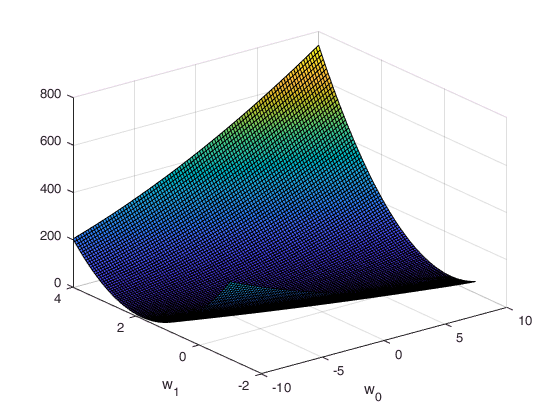

% Because of the way meshgrids work in the surf command, we need to
% transpose C_vals before calling surf, or else the axes will be flipped
C_vals = C_vals';
% Surface plot
figure;
surf(w0_vals, w1_vals, C_vals)
xlabel('w_0'); 
ylabel('w_1');

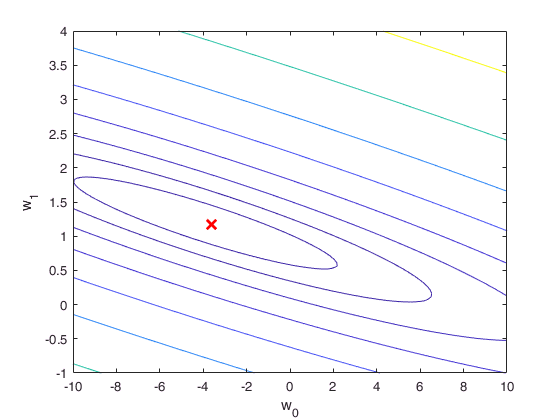


% Contour plot
figure;
% Plot C_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(w0_vals, w1_vals, C_vals, logspace(-2, 3, 20))
xlabel('w_0'); 
ylabel('w_1');
hold on;
plot(w(1), w(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);

***Functions:***

function C = computeCost(X,Y,w)
    m = length(Y);
    C = (sum(((X*w)-Y).^2))/(2*m);
end

function w = gradientDescent(X, Y, w, learning_rate, num_iters)
    % Initialize some useful values
    m = length(Y);     % number of training examples
    C_history = zeros(num_iters, 1);
    for i = 1:num_iters
        % WARNING: Simultaneously update 
        temp1 = w(1)-(learning_rate/m)*sum(X*w-Y); %*X(:,1) -> constant 1 (alias: BIAS)
        w(2) = w(2)-(learning_rate/m)*sum((X*w-Y).*X(:,2));
        w(1) = temp1;    
        C_history(i) = computeCost(X, Y, w);
    end
end
